## Modeling

### Question 1

#### Small angle approximation method

Using small angle approximation, we get $\left(m_{1}+m_{2}\right)\ddot{z}+\frac{m_{1}l}{2}\ddot{\theta} = f-b\dot{z}\quad\text{and}\quad \frac{l}{2}\ddot{\theta}+\ddot{z}-\mathrm{g}\theta = 0.$

Note that we are using $f$ for the input force instead of $F$. We will use $F$ for the Laplace transform of $f$. Writing these in a matrix form, we get 

$\left\lbrack \begin{array}{cc}
\left(m_{1}+m_{2}\right) & \frac{m_{1}l}{2}\\
1 & \frac{l}{2}
\end{array}\right\rbrack  \left\lbrack \begin{array}{c}
\ddot z\\\ddot\theta
\end{array}\right\rbrack = \left\lbrack \begin{array}{c}
f - b\dot z\\g\theta
\end{array}\right\rbrack$.

Inverting the matrix, we get expressions for $\ddot z$ and $\ddot \theta$ as

% Get problem parameters
cartPendulumParameters
% Create symbolic versions of the matrices above
syms s b m2 m1 g l b f z z_dot theta theta_dot z_ddot theta_ddot
M = [m1 + m2,  m1*l/2;
     1,        l/2];
c = [f - b*z_dot;
     g*theta];
derivs = simplify(inv(M)*c)

$$derivs = \left(\begin{array}{c} -\frac{b\,\dot{z}-f+g\,m_{1}\,\theta }{m_{2}}\\ \frac{2\,g\,\theta \,\left(m_{1}+m_{2}\right)}{l\,m_{2}}-\frac{2\,\left(f-b\,\dot{z}\right)}{l\,m_{2}} \end{array}\right)$$

eq1 = z_ddot == collect(derivs(1),[z_dot theta])

$$eq1 = \ddot{z}=\left(-\frac{b}{m_{2}}\right)\,\dot{z}+\left(-\frac{g\,m_{1}}{m_{2}}\right)\,\theta +\frac{f}{m_{2}}$$

eq2 = theta_ddot == collect(derivs(2),[z_dot theta])

$$eq2 = \ddot{\theta }=\frac{2\,b}{l\,m_{2}}\,\dot{z}+\frac{2\,g\,\left(m_{1}+m_{2}\right)}{l\,m_{2}}\,\theta -\frac{2\,f}{l\,m_{2}}$$

Taking the laplace transform (i.e., substituting s*Z for z_dot, s^2*Z for z_ddot, etc.,) we get

syms Z(s) Theta(s) F(s)
eq1 = collect(subs(eq1,[z_ddot,z_dot,theta,F],[s^2*Z(s), s*Z(s), Theta(s), F(s)]),[Z(s),Theta(s),F(s)])

$$eq1 = s^{2}\,Z\left(s\right)=\left(-\frac{b\,s}{m_{2}}\right)\,Z\left(s\right)+\left(-\frac{g\,m_{1}}{m_{2}}\right)\,\Theta \left(s\right)+\frac{f}{m_{2}}$$

eq2 = collect(subs(eq2,[theta_ddot,z_dot,theta,F],[s^2*Theta(s), s*Z(s), Theta(s), F(s)]),[Z(s),Theta(s),F(s)])

$$eq2 = s^{2}\,\Theta \left(s\right)=\frac{2\,b\,s}{l\,m_{2}}\,Z\left(s\right)+\frac{2\,g\,\left(m_{1}+m_{2}\right)}{l\,m_{2}}\,\Theta \left(s\right)-\frac{2\,f}{l\,m_{2}}$$

#### Jacobian linearization method

Without using small angle approximation, we have $\left(m_{1}+m_{2}\right)\ddot{z}+\frac{m_{1}l}{2}\ddot{\theta}\cos(\theta) - \frac{m_1 l}{2}\dot{\theta}^2\sin(\theta) = f-b\dot{z}$ and $\frac{l}{2}\theta^¨ +\ddot{z} \mathrm{cos}(\theta )-\mathrm{g}\mathrm{sin}(\theta )=0.$

Writing these in a matrix form, we get 

$\left\lbrack \begin{array}{cc}
\left(m_{1}+m_{2}\right) & \frac{m_{1}l\cos(\theta)}{2}\\
\cos(\theta) & \frac{l}{2}
\end{array}\right\rbrack  \left\lbrack \begin{array}{c}
\ddot z\\\ddot\theta
\end{array}\right\rbrack = \left\lbrack \begin{array}{c}
f - b\dot z + \frac{m_1 l}{2} \dot{\theta}^2\sin(\theta)\\g\sin(\theta)
\end{array}\right\rbrack$.

Inverting the matrix, we get expressions for $\ddot z$ and $\ddot \theta$ as

M = [m1+m2,       m1*l/2*cos(theta);
     cos(theta),  l/2;];
c = [f - b*z_dot + m1*l/2*theta_dot^2*sin(theta);...
     g*sin(theta)];
derivs = inv(M)*c;
z_ddot = derivs(1);
theta_ddot = derivs(2);

With the state

x = [z;theta;z_dot;theta_dot];

and the output $y=\left\lbrack \begin{array}{c}
z\\
\theta \;
\end{array}\right\rbrack$ we can express the equations in a state space form $\dot{x} = d(x,f)$ and $y=h(x,f)$ as

d = [z_dot; theta_dot; z_ddot; theta_ddot];
h = [z;theta];

Our reference trajectory for Jacobian linearization is $x^*(t) = 0$, $f^*(t) = 0$, and $y^*(t) = 0$ for all $t\in\left[0,\infty\right)$.

x_star = zeros(4,1);
f_star = 0;
y_star = zeros(2,1);

We can now linearize the system using symbolic math.

A = simplify(subs(jacobian(d,x),[x;f],[x_star;f_star]))

$$A = \left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1\\ 0 & -\frac{g\,m_{1}}{m_{2}} & -\frac{b}{m_{2}} & 0\\ 0 & \frac{2\,g\,\left(m_{1}+m_{2}\right)}{l\,m_{2}} & \frac{2\,b}{l\,m_{2}} & 0 \end{array}\right)$$

B = simplify(subs(jacobian(d,f),[x;f],[x_star;f_star]))

$$B = \left(\begin{array}{c} 0\\ 0\\ \frac{1}{m_{2}}\\ -\frac{2}{l\,m_{2}} \end{array}\right)$$

C = simplify(subs(jacobian(h,x),[x;f],[x_star;f_star]))

$$C = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 \end{array}\right)$$

D = simplify(subs(jacobian(h,f),[x;f],[x_star;f_star]))

$$D = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

We can then substitute the given values of parameters and convert the system from state space to a MIMO transfer function using the formula


$$H(s) = C(sI-A)^{-1}B + D$$


MIMO_TF_Jacobian = collect(simplify(C*inv(s*eye(4) - A)*B + D),s)

$$MIMO\_TF\_Jacobian = \begin{array}{l} \left(\begin{array}{c} \frac{\left(-l\right)\,s^{2}+2\,g}{\left(-l\,m_{2}\right)\,s^{4}+\left(-b\,l\right)\,s^{3}+\sigma_{1}\,s^{2}+\left(2\,b\,g\right)\,s}\\ \frac{2\,s}{\left(-l\,m_{2}\right)\,s^{3}+\left(-b\,l\right)\,s^{2}+\sigma_{1}\,s+2\,b\,g} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,g\,m_{1}+2\,g\,m_{2} \end{array}$$

Verify that this transfer function agrees with the one we found at the end of Question 2 below using the small angle approximation.

### Question 2

Starting from


$$$$\left(s^{2}+\frac{b}{m_{2}}s\right)Z\left(s\right)=\frac{1}{m_{2}}F\left(s\right)-\frac{m_{1}\mathrm{g}}{m_{2}}\Theta\left(s\right)$$$$
 

and

$\left(s^{2}-\frac{2\left(m_{1}+m_{2}\right)\mathrm{g}}{m_{2}l}\right)\Theta\left(s\right)=\frac{2b}{m_{2}l}sZ\left(s\right)-\frac{2}{m_{2}l}F\left(s\right)$,

we can write

$\left\lbrack \begin{array}{cc}
\left(s^{2}+\frac{b}{m_{2}}s\right) & \frac{m_{1}\mathrm{g}}{m_{2}}\\
-\frac{2b}{m_{2}l}s & \left(s^{2}-\frac{2\left(m_{1}+m_{2}\right)\mathrm{g}}{m_{2}l}\right)
\end{array}\right\rbrack  \left\lbrack \begin{array}{c}
Z\left(s\right)\\
\Theta\left(s\right)
\end{array}\right\rbrack = \left\lbrack \begin{array}{c}
\frac{1}{m_{2}}\\-\frac{2}{m_{2}l}
\end{array}\right\rbrack F\left(s\right)$.

By inverting the matrix, we get the MIMO transfer function.

% Create symbolic versions of the matrices above
M = [s^2 + b*s/m2, m1*g/m2;
     - 2*b*s/(m2*l), s^2 - 2*(m1 + m2)*g/(m2*l)];
c = [1/m2;  - 2/(m2*l)];
% Find the MIMO transfer function and the component transfer functions
MIMO_TF = collect(simplify(inv(M)*c),s)

$$MIMO\_TF = \begin{array}{l} \left(\begin{array}{c} \frac{\left(-l\right)\,s^{2}+2\,g}{\left(-l\,m_{2}\right)\,s^{4}+\left(-b\,l\right)\,s^{3}+\sigma_{1}\,s^{2}+\left(2\,b\,g\right)\,s}\\ \frac{2\,s}{\left(-l\,m_{2}\right)\,s^{3}+\left(-b\,l\right)\,s^{2}+\sigma_{1}\,s+2\,b\,g} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,g\,m_{1}+2\,g\,m_{2} \end{array}$$

H_ZF = MIMO_TF(1)

$$H\_ZF = \frac{\left(-l\right)\,s^{2}+2\,g}{\left(-l\,m_{2}\right)\,s^{4}+\left(-b\,l\right)\,s^{3}+\left(2\,g\,m_{1}+2\,g\,m_{2}\right)\,s^{2}+\left(2\,b\,g\right)\,s}$$

H_ThetaF = MIMO_TF(2)

$$H\_ThetaF = \frac{2\,s}{\left(-l\,m_{2}\right)\,s^{3}+\left(-b\,l\right)\,s^{2}+\left(2\,g\,m_{1}+2\,g\,m_{2}\right)\,s+2\,b\,g}$$

### Question 3

The poles of a MIMO transfer function are given by the union of the poles of the component transfer functions. In this case, since the demominator of $H_{ZF}$ and $H_{\Theta F}$ is the same except for multiplication by $s$, we can just look at the denominator of $H_{\Theta F}$ and add a pole at zero to the resulting list.

[~,den_H_ThetaF] = numden(H_ThetaF);
% extract denominator coefficients in the correct order
den_H_ThetaF_coeffs = flip(coeffs(den_H_ThetaF,'s'));
% substitute the given values
den_H_ThetaF_coeffs  = ...
    double(subs(den_H_ThetaF_coeffs,[b m1 m2 g l],[P.b P.m1 P.m2 P.g P.ell]));
% find roots and add pole at zero
MIMO_poles = [0; roots(den_H_ThetaF_coeffs)]

MIMO_poles =          0
    6.9950
   -7.0050
   -0.0400


### Question 4

Using cascade approximation, we get

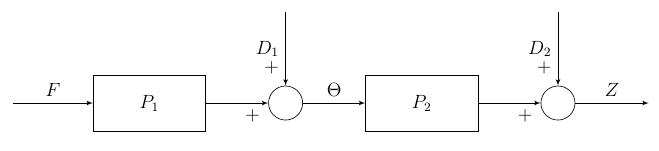

where

$P_1(s) = P_{in}(s) = \frac{\frac{-2}{m_{2}l}}{\left(s^{2}-\frac{2\left(m_{1}+m_{2}\right)\mathrm{g}}{m_{2}l}\right)},\quad \text{and}\quad P_2(s) = P_{out}(s) = \frac{\mathrm{g}}{s^{2}}$.

## Inner loop control design

### Question 5: Design

#### Desired characteristic polynomial:

Plotting the feasible region using the given specifications, we get:

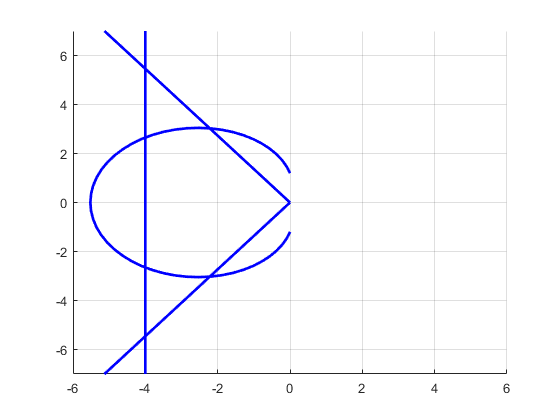

f_FeasibleRegion(6,7,'SettlingTimeUB',1,'RiseTimeUB',0.5,'OverShootUB',10);

Let us select the desired poles for the inner loop as

p_in_1 =  - 4 + 3i;
p_in_2 =  - 4 - 3i;

and create a symbolic expression for the desired characteristic polynomial along with a vector of coefficients of the desired characteristic polynomial.

delta_D_sym = collect((s - p_in_1)*(s - p_in_2),s)

$$delta\_D\_sym = s^{2}+8\,s+25$$

delta_D = flip(coeffs(delta_D_sym))

$$delta\_D = \left(\begin{array}{ccc} 1 & 8 & 25 \end{array}\right)$$

#### Actual characteristic polynomial:

The plant transfer function for the inner loop is

num_P_in = -2/(P.m2*P.ell);
den_P_in = [1 0 (-2*P.g*(P.m1 + P.m2)/(P.m2*P.ell))];
P_in = tf(num_P_in,den_P_in);

To use MATLAB for this design, let us create a symbolic version of the plant and the controller transfer functions.

syms kd_in_Sym kp_in_Sym
P_in_Sym = poly2sym(num_P_in,s)/poly2sym(den_P_in,s);
C_in_Sym = kd_in_Sym*s + kp_in_Sym;

Then, we calculate the closed - loop transfer function, extract its denominator, and extract the coefficients of that denominator in a symbolic form.

H_in_Sym = C_in_Sym*P_in_Sym/(1 + C_in_Sym*P_in_Sym);
[num_H_in_Sym,den_H_in_Sym] = numden(H_in_Sym);
delta_A_sym = den_H_in_Sym

$$delta\_A\_sym = -s^{2}+4\,{\mathrm{kd}}_{\mathrm{in},\mathrm{Sym}}\,s+4\,{\mathrm{kp}}_{\mathrm{in},\mathrm{Sym}}+49$$

delta_A = flip(coeffs(den_H_in_Sym,s));
delta_A = delta_A/delta_A(1)

$$delta\_A = \left(\begin{array}{ccc} 1 & -4\,{\mathrm{kd}}_{\mathrm{in},\mathrm{Sym}} & -4\,{\mathrm{kp}}_{\mathrm{in},\mathrm{Sym}}-49 \end{array}\right)$$

Now we match $\Delta_a$ and $\Delta_d$ to get values of the gains $kp_{in}$ and $kd_{in}$

eqn = delta_D(2:end) - delta_A(2:end) == zeros(size(delta_D(2:end)));
S_in = solve(eqn);
P.kd_in = double(S_in.kd_in_Sym);
P.kp_in = double(S_in.kp_in_Sym);

### Question 6: Verification

Now we create non symbolic transfer functions for the controller and the closed loop and check for stability and step response.

C_in = tf([P.kd_in P.kp_in],1);
H_Theta_ThetaR = feedback(P_in*C_in,1);
InnerLoopStable = isstable(H_Theta_ThetaR)

InnerLoopStable = logical
   1


InnerLoopStepInfo = stepinfo(H_Theta_ThetaR)

InnerLoopStepInfo = struct with fields:
        RiseTime: 0.4207
    SettlingTime: 0.5936
     SettlingMin: 2.6725
     SettlingMax: 3.0186
       Overshoot: 1.9807
      Undershoot: 0
            Peak: 3.0186
        PeakTime: 0.8750


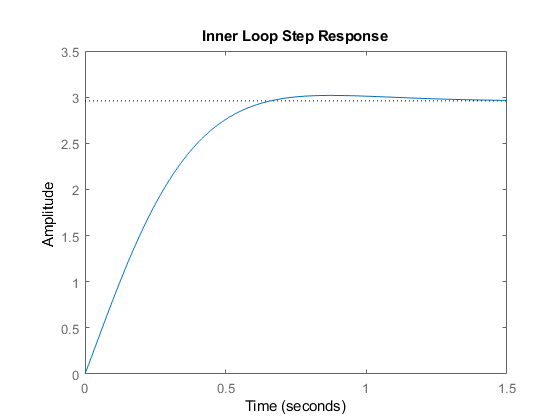

step(H_Theta_ThetaR); title('Inner Loop Step Response');

We also calculate the DC gain of the closed inner loop for use in outer - loop control design.

kDC_in = dcgain(H_Theta_ThetaR);

## Outer - loop control design

The plant we use for outer - loop control design is $H_{\Theta\Theta_R}(0) P_{2}(s) = k_{DC,in}P_{out}(s)$. The remaining procedure is similar to the inner loop design. 

### Question 7: Design

#### Desired characteristic polynomial:

Plotting the feasible region using the given specifications, we get (upper bounds in red and lower bounds in blue):

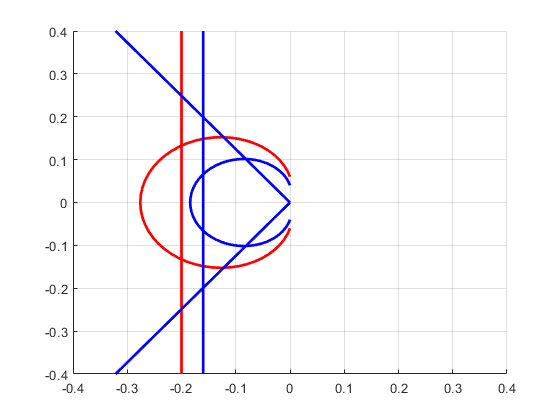

f_FeasibleRegion(0.4,0.4,'SettlingTimeUB',25,'RiseTimeUB',15,'SettlingTimeLB',20,'RiseTimeLB',10,'OverShootUB',8);

Let us select the desired poles for the outer loop as

p_out_1 =  - 0.2 + 0.1i;
p_out_2 =  - 0.2 - 0.1i;

and create a symbolic expression for the desired characteristic polynomial along with a vector of coefficients of the desired characteristic polynomial.

delta_D_sym = collect((s - p_out_1)*(s - p_out_2),s)

$$delta\_D\_sym = s^{2}+\frac{2\,s}{5}+\frac{1}{20}$$

delta_D = flip(coeffs(delta_D_sym))

$$delta\_D = \left(\begin{array}{ccc} 1 & \frac{2}{5} & \frac{1}{20} \end{array}\right)$$

#### Actual characteristic polynomial:

The plant transfer function for the inner loop is

num_P_out = [P.g];
den_P_out = [1 0 0];
P_out = tf(num_P_out,den_P_out);

To use MATLAB for this design, let's create a symbolic version of the plant and the controller transfer functions.

syms kd_out_Sym kp_out_Sym
P_out_Sym = poly2sym(num_P_out,s)/poly2sym(den_P_out,s);
C_out_Sym = kd_out_Sym*s + kp_out_Sym;

Then, we calculate the closed - loop transfer function, extract its denominator, and extract the coefficients of that denominator in a symbolic form.

H_out_Sym = kDC_in*C_out_Sym*P_out_Sym/(1 + kDC_in*C_out_Sym*P_out_Sym);
[num_H_out_Sym,den_H_out_Sym] = numden(H_out_Sym);
delta_A_sym = den_H_out_Sym

$$delta\_A\_sym = 125\,s^{2}+3626\,{\mathrm{kd}}_{\mathrm{out},\mathrm{Sym}}\,s+3626\,{\mathrm{kp}}_{\mathrm{out},\mathrm{Sym}}$$

delta_A = flip(coeffs(den_H_out_Sym,s));
delta_A = delta_A/delta_A(1)

$$delta\_A = \left(\begin{array}{ccc} 1 & \frac{3626\,{\mathrm{kd}}_{\mathrm{out},\mathrm{Sym}}}{125} & \frac{3626\,{\mathrm{kp}}_{\mathrm{out},\mathrm{Sym}}}{125} \end{array}\right)$$

Now we match $\Delta_a$ and $\Delta_d$ to get values of the gains $kp_{out}$ and $kd_{out}$

eqn = delta_D(2:end) - delta_A(2:end) == zeros(size(delta_D(2:end)));
S_out = solve(eqn);
P.kd_out = double(S_out.kd_out_Sym);
P.kp_out = double(S_out.kp_out_Sym);

### Question 8: Verification

C_out = tf([P.kd_out P.kp_out],1);
H_Z_ZR = feedback(P_out*C_out*kDC_in,1);
OuterLoopStable = isstable(H_Z_ZR)

OuterLoopStable = logical
   1


OuterLoopStepInfo = stepinfo(H_Z_ZR)

OuterLoopStepInfo = struct with fields:
        RiseTime: 3.4388
    SettlingTime: 23.3550
     SettlingMin: 0.9263
     SettlingMax: 1.1565
       Overshoot: 15.6502
      Undershoot: 0
            Peak: 1.1565
        PeakTime: 9.2103


Note that this closed loop does not satisfy the performance requirements we started with. Some trial and error with selection of the desired poles is needed to get the right answer.

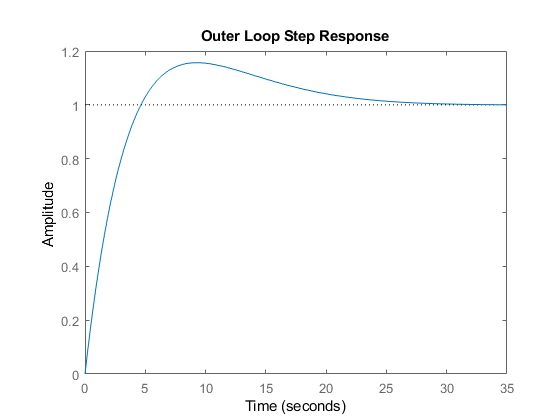

step(H_Z_ZR); title('Outer Loop Step Response');

## Putting it all together

### Question 9: Simulation

Open 'cartPendulumSim.slx' to see how the simulation is put together.

sim('cartPendulumSim.slx');

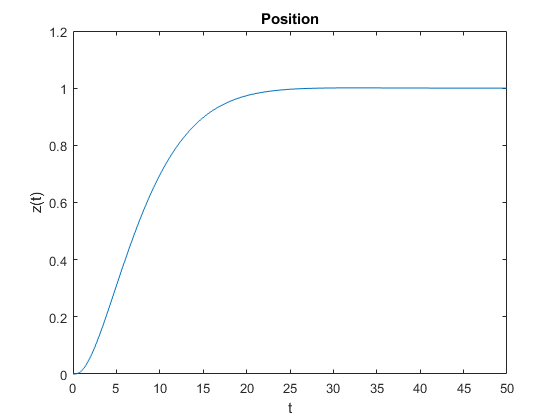

plot(z.time,z.signals.values); xlabel('t'); ylabel('z(t)'); title('Position');

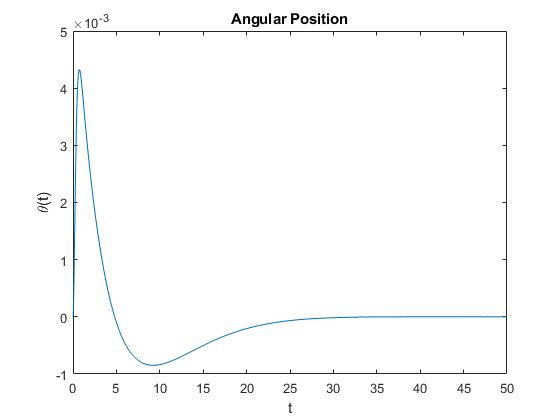

plot(theta.time,theta.signals.values); xlabel('t'); ylabel('\theta(t)'); title('Angular Position');

### Question 10

The final closed-loop transfer function from $Z_R$ to $\Theta $ is given by


$$H_{\Theta Z_R} = \frac{C_{out}H_{\Theta\Theta_R}}{1+C_{out}H_{\Theta\Theta_R}P_{out}}$$


and the final closed-loop transfer function from $Z_R$ to $Z$ is given by


$$H_{ZZ_R} = \frac{C_{out}H_{\Theta\Theta_R}P_{out}}{1+C_{out}H_{\Theta\Theta_R}P_{out}}$$


where, instead of using the constant approximation $H_{\Theta\Theta_R}(0)$ for the fast inner loop, we are using the actual transfer function $H_{\Theta\Theta_R}$.

H_Theta_ZR_actual = minreal(C_out*H_Theta_ThetaR/(1 + C_out*H_Theta_ThetaR*P_out));
ThetaZRStable = isstable(H_Theta_ZR_actual)

ThetaZRStable = logical
   1


H_Z_ZR_actual = minreal(C_out*P_out*H_Theta_ThetaR/(1 + C_out*H_Theta_ThetaR*P_out));
ZZRStable = isstable(H_Z_ZR_actual)

ZZRStable = logical
   1
